addpath('VERSION ANTERIOR APIMO\');
addpath('VERSION ANTERIOR APIMO\API_MO');
addpath('src\');
SOFAstart;
addpath('VERSION ANTERIOR APIMO\HRTFs\SADIE\D1_HRIR_SOFA')
hrtf = SOFAload('D1_44K_16bit_256tap_FIR_SOFA.sofa');
% addpath('VERSION ANTERIOR APIMO\HRTFs\ARI\')
% hrtf = SOFAload('ARI_NH2_hrtf_M_dtf 256.sofa');
%SOFAinfo(hrtf)
%SOFAplotGeometry(hrtf);
%hrtf2 = SOFAload('D1_48K_24bit_256tap_FIR_SOFA.sofa');
%SOFAplotGeometry(hrtf2);

%hrtf3 = SOFAload('D1_96K_24bit_512tap_FIR_SOFA.sofa');
%SOFAplotGeometry(hrtf3);

%size(hrtf.Data.IR)
%hrtf.Data.IR

%hrtf.ListenerPosition
%hrtf.SourcePosition
%hrtf3.SourcePosition
%apparentSourceVector = SOFAcalculateAPV(hrtf)
%demoThreshold(hrtf)

# Pruebas con el threshold para la distancia

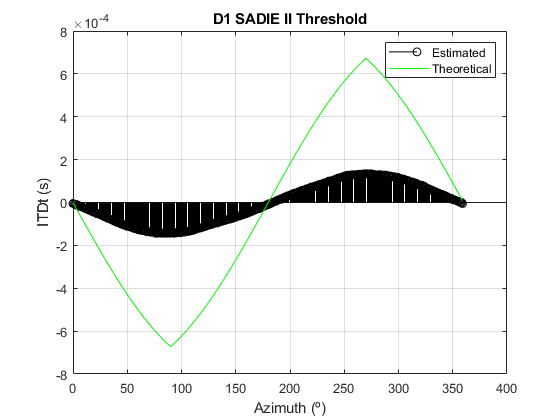

Phor = find(hrtf.SourcePosition(:,2) < -80 &  hrtf.SourcePosition(:,2) > -85); % Obtención de las muestras en el plano horizontal.
ITDt = zeros(1,length(Phor));
ITDw = zeros(1,length(Phor));
theta = hrtf.SourcePosition(Phor,1);
for x = 1:length(Phor)
    ITDt(x) = Threshold(hrtf, hrtf.SourcePosition(Phor(x),1), hrtf.SourcePosition(Phor(x),2));
    if theta(x) > 90 && theta(x) < 270
        theta(x) = 180-theta(x);
    elseif theta(x) >= 270
        theta(x) = theta(x) - 360;    
    end
    ITDw(x) = -(0.09/344)*(theta(x)*pi/180 + sin(theta(x)*pi/180));
    if strcmp(hrtf.GLOBAL_DatabaseName, 'CIPIC')
        ITDw(x) = -1*ITDw(x);
    end
end    

figure();
stem(hrtf.SourcePosition(Phor), ITDt, 'k'); title([hrtf.GLOBAL_ListenerShortName ' ' hrtf.GLOBAL_DatabaseName ' Threshold']);
xlabel('Azimuth (º)'); ylabel('ITDt (s)'); grid on; hold on;
plot(hrtf.SourcePosition(Phor,1), ITDw, 'g');
legend('Estimated', 'Theoretical');
hold off;

ECM = sum((ITDw-ITDt).^2)/length(ITDt)

ECM = 1.0722e-07

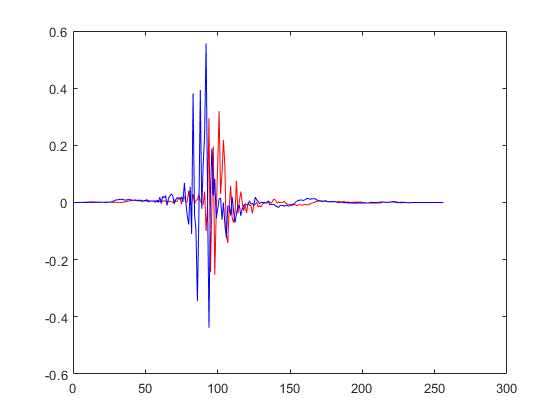

x = 1:length(hrtf.Data.IR(13,2,:));
L = squeeze(hrtf.Data.IR(13,2,:));
plot(x,L, 'r')
hold on;
Pos = abs(hrtf.SourcePosition(:,2)) < 10^-10 & abs(hrtf.SourcePosition(:,1)) == 270;
L2 = squeeze(hrtf.Data.IR(Pos,2,:));
plot(x,L2, 'b')
hold off;

# Grafico de los retardos del oido derecho respecto a la misma elevacion

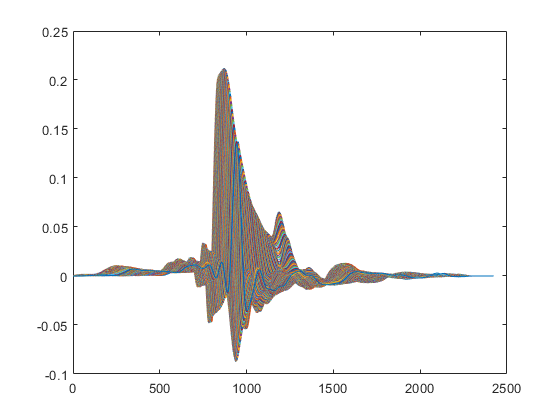

% DEMOTHRESHOLD Estimates ITD by Threshold method for a SOFA given around
% all horizontal plane.
% 
%hrtf -> SOFA file given
%
%ITDt -> ITD vector with all angles on horizontal plane
%Phor === Plano horizontal
    Phor = find(abs(hrtf.SourcePosition(:,2)) < 10^-10); % Obtención de las posiciones en el plano horizontal en el que la elevacion es 0.
    tR = zeros(1,length(Phor)); %Vector columna
    tL = zeros(1,length(Phor)); %Vector columna
    theta = hrtf.SourcePosition(Phor,1); %El azimuth en el que la elevación es 0
    for x = 1:length(Phor)
        tR(x) = RetardosR(hrtf, hrtf.SourcePosition(Phor(x),1), hrtf.SourcePosition(Phor(x),2)); %Calcula los retardos y plotea
        %tL(x) = RetardosL(hrtf, hrtf.SourcePosition(Phor(x),1), hrtf.SourcePosition(Phor(x),2)); %Calcula los retardos
        if theta(x) > 90 && theta(x) < 270
            theta(x) = 180-theta(x);
        elseif theta(x) >= 270
            theta(x) = theta(x) - 360;    
        end
    end    
    hold off;

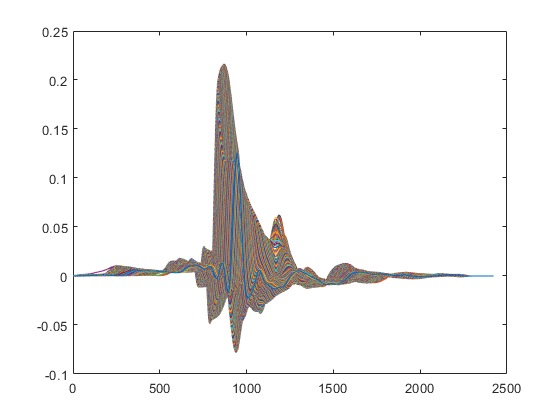

    for x = 1:length(Phor)
        tL(x) = RetardosL(hrtf, hrtf.SourcePosition(Phor(x),1), hrtf.SourcePosition(Phor(x),2)); %Calcula los retardos
    end

Aqui se muestra las graficas de cada muestra del oido derecho.

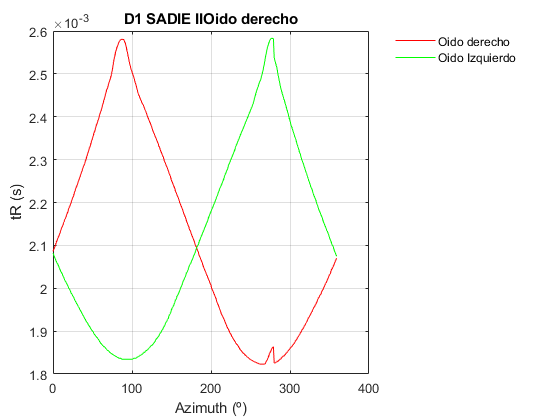

    figure();
    plot(hrtf.SourcePosition(Phor), tR, 'r'); title([hrtf.GLOBAL_ListenerShortName ' ' hrtf.GLOBAL_DatabaseName 'Oido derecho']);
    xlabel('Azimuth (º)'); ylabel('tR (s)'); grid on; hold on;
    plot(hrtf.SourcePosition(Phor,1), tL, 'g');
    legend('Oido derecho', 'Oido Izquierdo','Location',"northeastoutside");
    legend('boxoff')
    hold off;

Aqui se muestra la diferencia de tiempos del oido izquierdo y el derecho en función del azimuth

# Quitar el retardo

Voy a buscar las respuestas al impulso de Azimuth: 0, 90, 180, 270 para el oido derecho y elevación 0. Primero se mostrarán las 4 señales con sus retardos. Luego tratare de quitarles el retardo y ajustarlas al inicio de la gráfica.

Pos = [];
% for i=1:8802
%     if abs(hrtf.SourcePosition(i,2)) < 10^-10 && hrtf.SourcePosition(i,1) == 
%         Pos = [Pos i];
%     end
% end


%PosE busca las posiciones que tengan elevacion 0, y PosA busca en azimuth las posiciones de 0,
%90, 180 y 270 grados
PosE = find(abs(hrtf.SourcePosition(:,2)) < 10^-10, 400); %posicion elevacion. Busco las 400 muestras que hay
PosA = find(abs(hrtf.SourcePosition(:,1)) == 0 | abs(hrtf.SourcePosition(:,1)) == 90 | abs(hrtf.SourcePosition(:,1)) == 180 | abs(hrtf.SourcePosition(:,1)) == 270, 100);
PosE = PosE'; %Las convierto de columnas a filas
PosA = PosA';
%L2 = squeeze(hrtf.Data.IR(Pos,2,:));
%plot(x,L2, 'b')
%Comparo las posiciones y me quedo con las que se repiten
for x = 1:length(PosA)
    for y = 1:length(PosE)
        if PosA(x) == PosE(y)
            Pos = [Pos PosE(y)];
        end
    end
end
Pos;  %Son las posiciones de 0º 90º 180º y 270º con elevacion 0º

Grafica

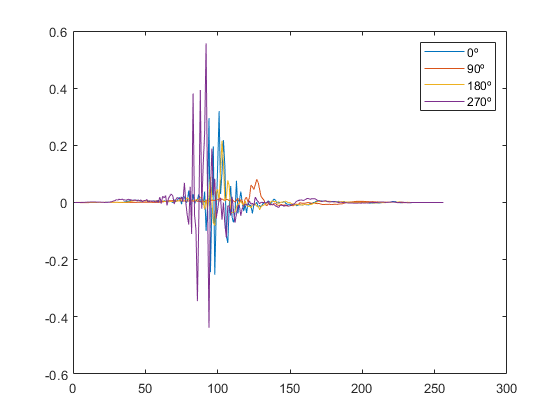

clear G;
for i=1:length(Pos)
    x = 1:length(hrtf.Data.IR(Pos(i),2,:));%squeeze() remueve las dimensiones de tamaño 1. A(2x2) =
    %squeeze(A(2x1x2)
    R = squeeze(hrtf.Data.IR(Pos(i),2,:));
    G(i) = plot(x,R);
    hold on;
end
legend(G,'0º','90º','180º','270º');
hold off;

%frecuencia de muestreo (es otro nombre)
fs = hrtf.Data.SamplingRate;
T = 1/fs; %Tiempo que dura cada punto discretizado
Ret = []; %tiempo de cada retardo
format long;
clear Ret;
Ret = length(Pos)

Ret =      4


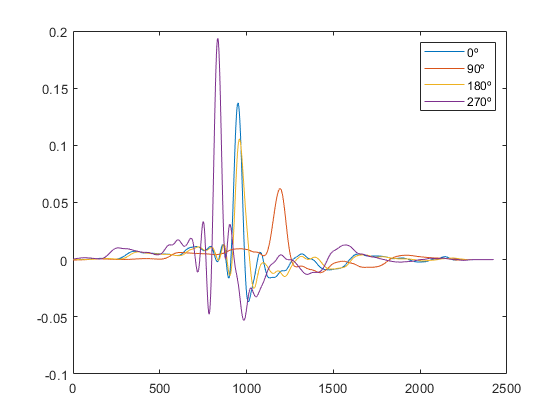

for i = 1:length(Pos)
    Ret(i) = RetardosR(hrtf, hrtf.SourcePosition(Pos(i),1), hrtf.SourcePosition(Pos(i),2));
end
%legend(Ret,'0º','90º','180º','270º','Location','northeast')
legend({'0º','90º','180º','270º'})
hold off;

Ret; %retardos de cada señal
Tt = 1/fs*256; %%tiempo total que dura cada muestra del hrtf
SRet = Tt - Ret; %tiempo que dura la muestra sin el retardo
M = round(SRet/T) %Duracion de cada muestra discretizada sin retardo

M =    164   142   163   175


M2 = round(Ret/T) %Numero de posicion de finalizacion del retarddo de cada muestra

M2 =     92   114    93    81


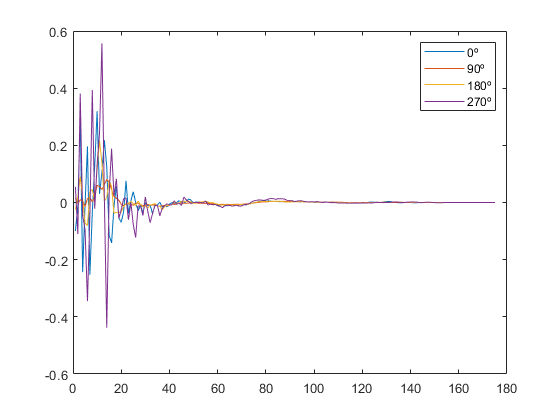

%M2 = 256 - M % Indica en que numero empieza
clear G;
for i=1:length(Pos)
    x = 1:M(i);
    R = squeeze(hrtf.Data.IR(Pos(i),2,M2(i):(256-1)));
    G(i) = plot(x,R);
    hold on;
end
legend(G,'0º','90º','180º','270º')
hold off;

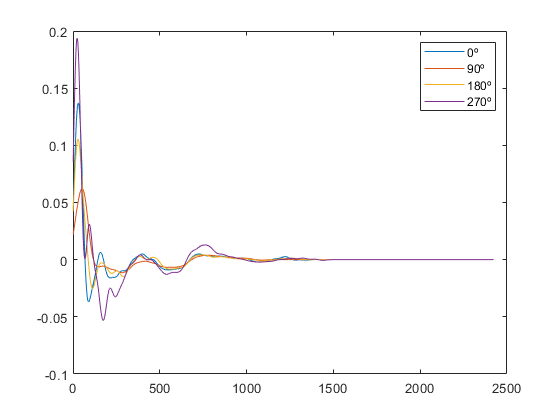

clear G;
for x = 1:length(Pos)
    G(x) = GraficaSinRet(hrtf, Pos(x), M2(x), 2);
end
legend(G,'0º','90º','180º','270º')
hold off;

Una muestra sola. La azul es la original y la roja con el retardo quitado

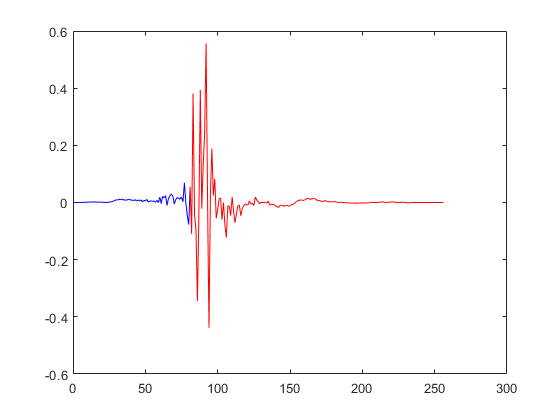

x = 1:length(hrtf.Data.IR(Pos(4),2,:));
R = squeeze(hrtf.Data.IR(Pos(4),2,:));
plot(x,R,'b')
hold on;

x = M2(4):length(hrtf.Data.IR(Pos(4),2,:));
R = squeeze(hrtf.Data.IR(Pos(4),2,M2(4):256));
plot(x,R,'r')
hold off;

El retardo parece ser que se ha calculado con los puntos maximos. Tengo que encontrar otra manera, pero tal vez pueda alinear las señales para que empiecen desde el mismo instante, aunque este no sea 0.

minimo = min(M2); 
M3 = M2-minimo

M3 =     11    33    12     0


M3(4) = M3(4)+1

M3 =     11    33    12     1


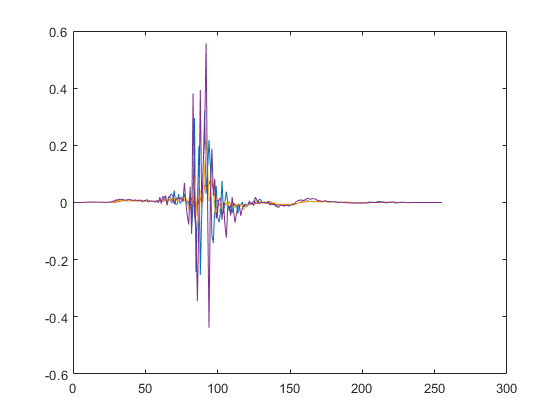

for i=1:length(Pos)
    x = 1:(256-M3(i));
    R = squeeze(hrtf.Data.IR(Pos(i),2,M3(i):255));
    plot(x,R)
    hold on;
end
hold off;

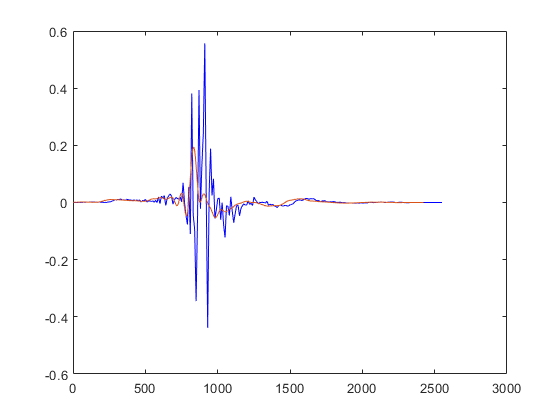

A = reshape(hrtf.Data.IR(Pos(4),1,:), [1, length(hrtf.Data.IR(Pos(4),1,:))]); %%convertimos este vector en 1x512
B = reshape(hrtf.Data.IR(Pos(4),2,:), [1, length(hrtf.Data.IR(Pos(4),2,:))]);

%% Oversampling
OS = 10; % Oversampling factor
ta = 0:1/fs:(length(A)-1)/fs;
ty = 0:1/(OS*fs):(length(A)-1)/(fs);
L = interp1(ta,A,ty); %% Oversampling x10
R = interp1(ta,B,ty);
x = 1:length(R);
%R = squeeze(hrtf.Data.IR(Pos(4),2,:));
plot(x,R,'b');
hold on;
    
RetardosR(hrtf, hrtf.SourcePosition(Pos(4),1), hrtf.SourcePosition(Pos(4),2));
hold off;

%0 grados
x = 1:length(hrtf.Data.IR(Pos(1),2,:));

Unrecognized function or variable 'Pos'.

R = squeeze(hrtf.Data.IR(Pos(1),2,:));
plot(x,R);
hold on;
%270 grados
x = 1:length(hrtf.Data.IR(Pos(4),2,:));
R = squeeze(hrtf.Data.IR(Pos(4),2,:));
plot(x,R);
hold off;
M2
x = 1:M(1)
R = squeeze(hrtf.Data.IR(Pos(1),2,M2(1):(256-1)));
plot(x,R)
hold on;
x = 1:M(4);
R = squeeze(hrtf.Data.IR(Pos(4),2,M2(4):(256-1)));
plot(x,R)
hold off;

Filtrar el HRIR y filtrar el umbral. EL filtro mete un retardo debido a la frecuencia.

Estudiar el retardo del filtro FIR, como calcularlo


 hrtf.SourcePosition

ans =          0  -90.0000    1.2000
         0  -81.0000    1.2000
         0  -75.0000    1.2000
         0  -64.8000    1.2000
         0  -60.0000    1.2000
         0  -54.0000    1.2000
         0  -45.0000    1.2000
         0  -35.3000    1.2000
         0  -30.0000    1.2000
         0  -25.0000    1.2000
